# Horizontal EOG gaze-angle estimation with a vector Kalman filter

**Dataset:** Barbara, Camilleri & Camilleri, Univ. of Malta, "Eye movement EOG data".

**Method:** 

(1) least-squares calibration of the gain g (uV/deg) from saccade step sizes, 

(2) vector Kalman filter with state [gaze angle; drift] and saccade-switched process noise.

Model: EOG = g * gaze + drift + noise

clear; clc; close all;
set(0,'DefaultAxesFontSize',16,'DefaultLineLineWidth',1.5);

## 1. Configuration

cfg.dataDir = ['S5'];  % Participant No.
cfg.fs      = 256;     % sampling rate
cfg.nCal    = 20;      % initial trials used for LS calibration


% Kalman tuning (tuned on subject S1)
cfg.R       = 6;       % measurement nois
%  variance (uV^2)
cfg.qDrift  = 60;      % drift process noise (uV^2/sample)
cfg.qSacc   = 1000;    % gaze process noise during saccades (deg^2/sample)
cfg.tau     = 5;       % gaze mean-reversion time constant (s)
cfg.sigTheta= 20;      % prior std of gaze about the centre (deg)
cfg.sacThr  = 8;       % saccade detector threshold (x robust velocity sigma)
cfg.holdSec = 0.08;    % saccade flag widening (s)

## 2. Loading Data

if isfolder(cfg.dataDir)
    S = load(fullfile(cfg.dataDir,'EOG.mat'));           EOG = S.EOG;
    S = load(fullfile(cfg.dataDir,'ControlSignal.mat')); C = double(S.ControlSignal(:)');
    S = load(fullfile(cfg.dataDir,'TargetGA.mat'));      tgt = S.TargetGA(1:2:end,1);
else
    fprintf('Folder "%s" not found \n', cfg.dataDir);
    return;
    
end

## **3. Ground Generation**

C(C > 3) = 3;                                        % stray label (30) at the end -> blink
y = EOG(1,:)';  fs = cfg.fs;  N = numel(y);
ch = [1, find(diff(C) ~= 0) + 1];  st = ch;  en = [ch(2:end) - 1, N];  lab = C(st);
fw = [st(lab==1)', en(lab==1)'];  rt = [st(lab==2)', en(lab==2)'];  bl = [st(lab==3)', en(lab==3)'];
nTr = size(fw,1);
truth = nan(N,1);
for i = 1:nTr
    L = fw(i,2)-fw(i,1)+1;  truth(fw(i,1)+floor(0.7*L):fw(i,2)) = tgt(i);
    L = rt(i,2)-rt(i,1)+1;  truth(rt(i,1)+floor(0.7*L):rt(i,2)) = 0;
    truth(bl(i,1):bl(i,2)) = 0;
end
% calibration fixation levels (time order): target level, then centre level, then next target ...
lv = [];  an = [];
for i = 1:cfg.nCal
    if i > 1, lv(end+1) = mean(y(bl(i-1,2)-99:bl(i-1,2))); an(end+1) = 0; end
    lv(end+1) = mean(y(fw(i,2)-49:fw(i,2)));  an(end+1) = tgt(i);
end

t = (0:N-1)'/fs;
lv = lv(:);  an = an(:);

## 3. Least-squares calibration of the gain g (initial trials only)

Absolute EOG levels contain drift, so we fit the **jumps** between consecutive fixations

dy  = diff(lv);                 % measured EOG jumps (uV)
dth = diff(an);                 % known angle changes (deg) from TargetGA
g   = ls_calibrate(lv, an);
fprintf('LS calibration: g = %.2f uV/deg (from %d jumps)\n', g, numel(dy));

LS calibration: g = 16.27 uV/deg (from 38 jumps)


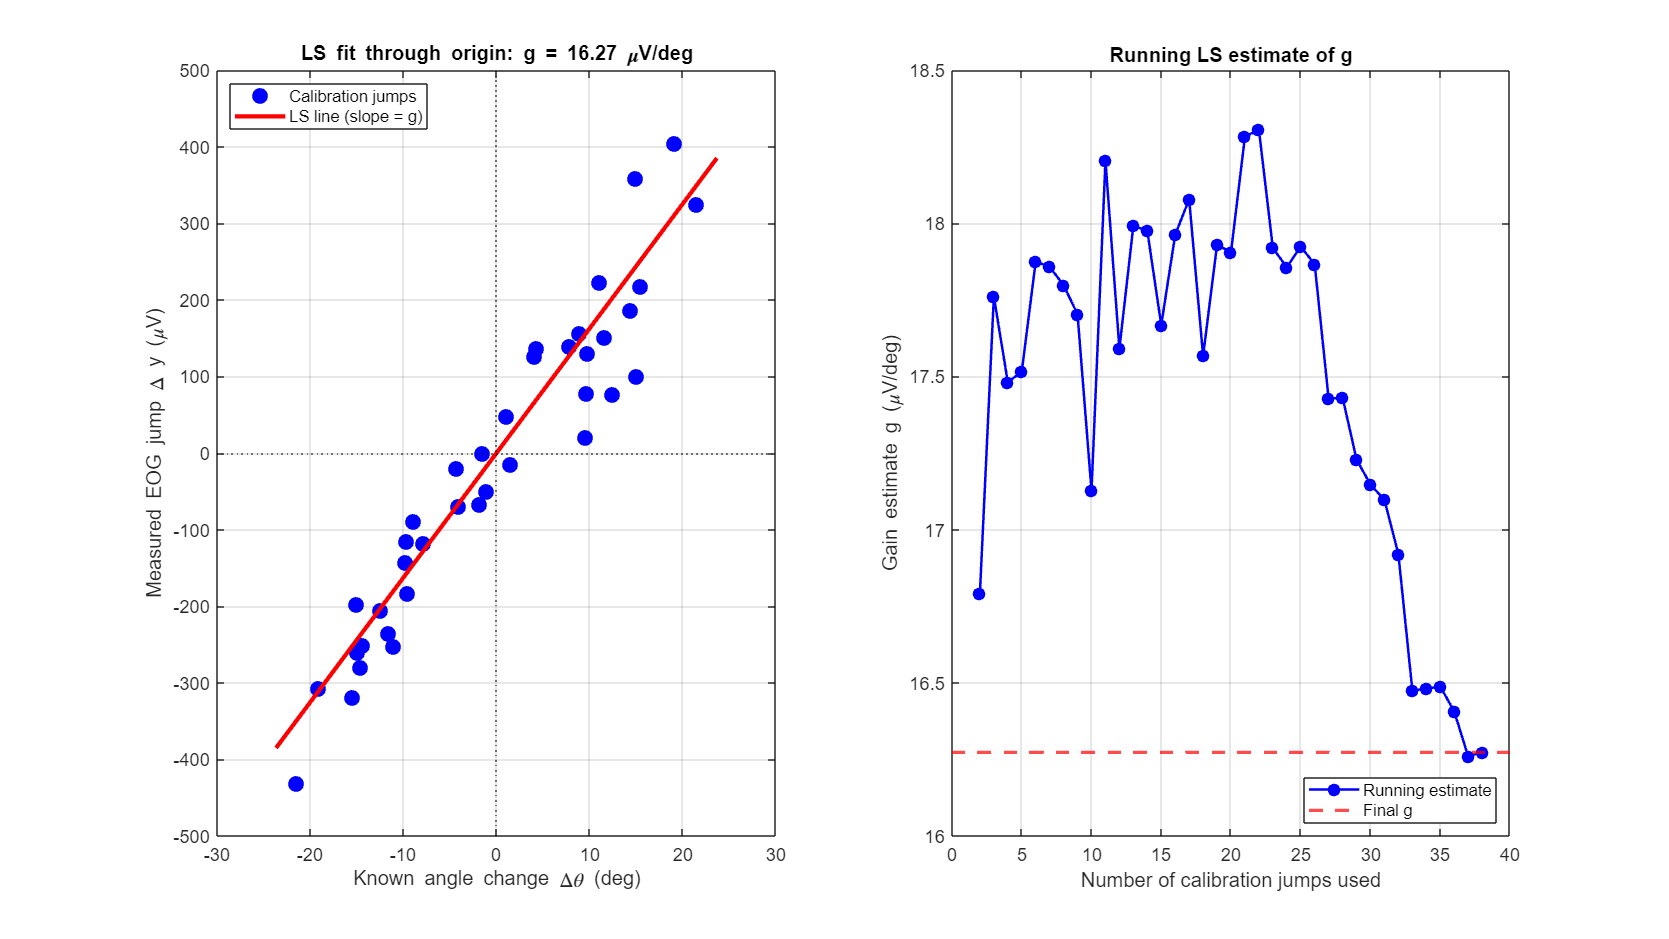


% g estimate as more jumps are included (running LS estimate)
nJ  = numel(dy);
gRun = nan(nJ,1);
for k = 2:nJ
    gRun(k) = (dth(1:k)' * dy(1:k)) / (dth(1:k)' * dth(1:k));
end

fig1 = figure('Position',[50 50 1920 1080],'Color','w');
set(0,'DefaultAxesFontSize',11)
subplot(1,2,1);
plot(dth, dy, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b'); hold on;
xl = [min(dth) max(dth)] * 1.1;  plot(xl, g*xl, 'r', 'LineWidth', 2.5);
yline(0,'k:'); xline(0,'k:'); grid on;
xlabel('Known angle change \Delta\theta (deg)'); ylabel('Measured EOG jump \Delta y (\muV)');
title(sprintf('LS fit through origin: g = %.2f \\muV/deg', g));
legend('Calibration jumps','LS line (slope = g)','Location','northwest');
subplot(1,2,2);
plot(2:nJ, gRun(2:end), 'b-o', 'MarkerFaceColor','b'); hold on; yline(g,'r--','LineWidth',2);
grid on; xlabel('Number of calibration jumps used'); ylabel('Gain estimate g (\muV/deg)');
title('Running LS estimate of g'); legend('Running estimate','Final g','Location','southeast');

## 4. Saccade detection and Kalman filter

isSacc = detect_saccades(y, fs, cfg.sacThr, cfg.holdSec);
[theta, drift] = kalman_gaze_drift(y, g, cfg.R, cfg.qDrift, cfg.qSacc, isSacc, cfg.tau, cfg.sigTheta, fs);
thetaNaive = (y - y(1)) / g;        % no drift handling, for comparison

## 5. Performance metrics

m = ~isnan(truth);
rmse = @(a,b) sqrt(mean((a-b).^2));
fprintf('\nGaze-angle RMSE (evaluated where truth is known):\n');


Gaze-angle RMSE (evaluated where truth is known):


fprintf('   naive (no drift removal): %.2f deg\n   Kalman                  : %.2f deg\n', ...
        rmse(thetaNaive(m),truth(m)), rmse(theta(m),truth(m)));

   naive (no drift removal): 76.75 deg
   Kalman                  : 3.23 deg


fprintf('   Saccade samples flagged: %.1f %%\n', 100*mean(isSacc));

   Saccade samples flagged: 3.7 %


## 6. Results: full recording

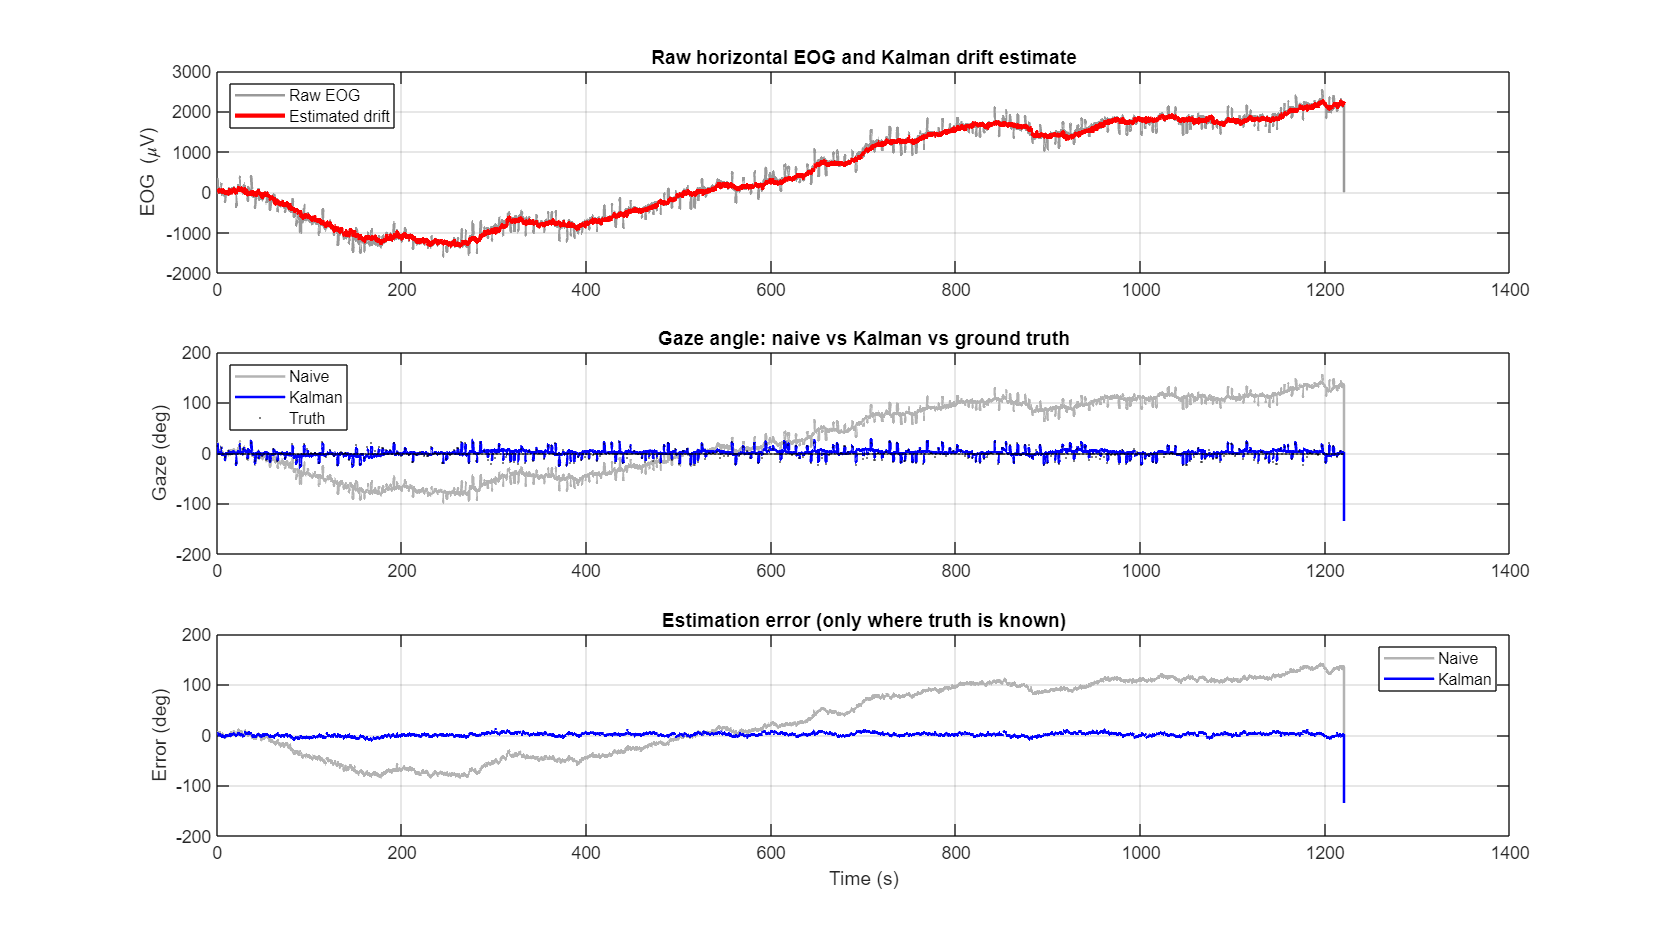

fig2 = figure('Position',[50 50 1920 1080],'Color','w');
subplot(3,1,1); plot(t,y,'Color',[.6 .6 .6]); hold on; plot(t,drift,'r','LineWidth',2.5);
ylabel('EOG (\muV)'); title('Raw horizontal EOG and Kalman drift estimate'); grid on;
legend('Raw EOG','Estimated drift','Location','northwest');
subplot(3,1,2); plot(t,thetaNaive,'Color',[.7 .7 .7]); hold on; plot(t,theta,'b');
plot(t,truth,'k.','MarkerSize',3); ylabel('Gaze (deg)'); grid on;
title('Gaze angle: naive vs Kalman vs ground truth'); legend('Naive','Kalman','Truth','Location','northwest');
subplot(3,1,3); plot(t,thetaNaive-truth,'Color',[.7 .7 .7]); hold on; plot(t,theta-truth,'b');
ylabel('Error (deg)'); xlabel('Time (s)'); grid on;
title('Estimation error (only where truth is known)'); legend('Naive','Kalman');

## 7. Results: 8-second zoom

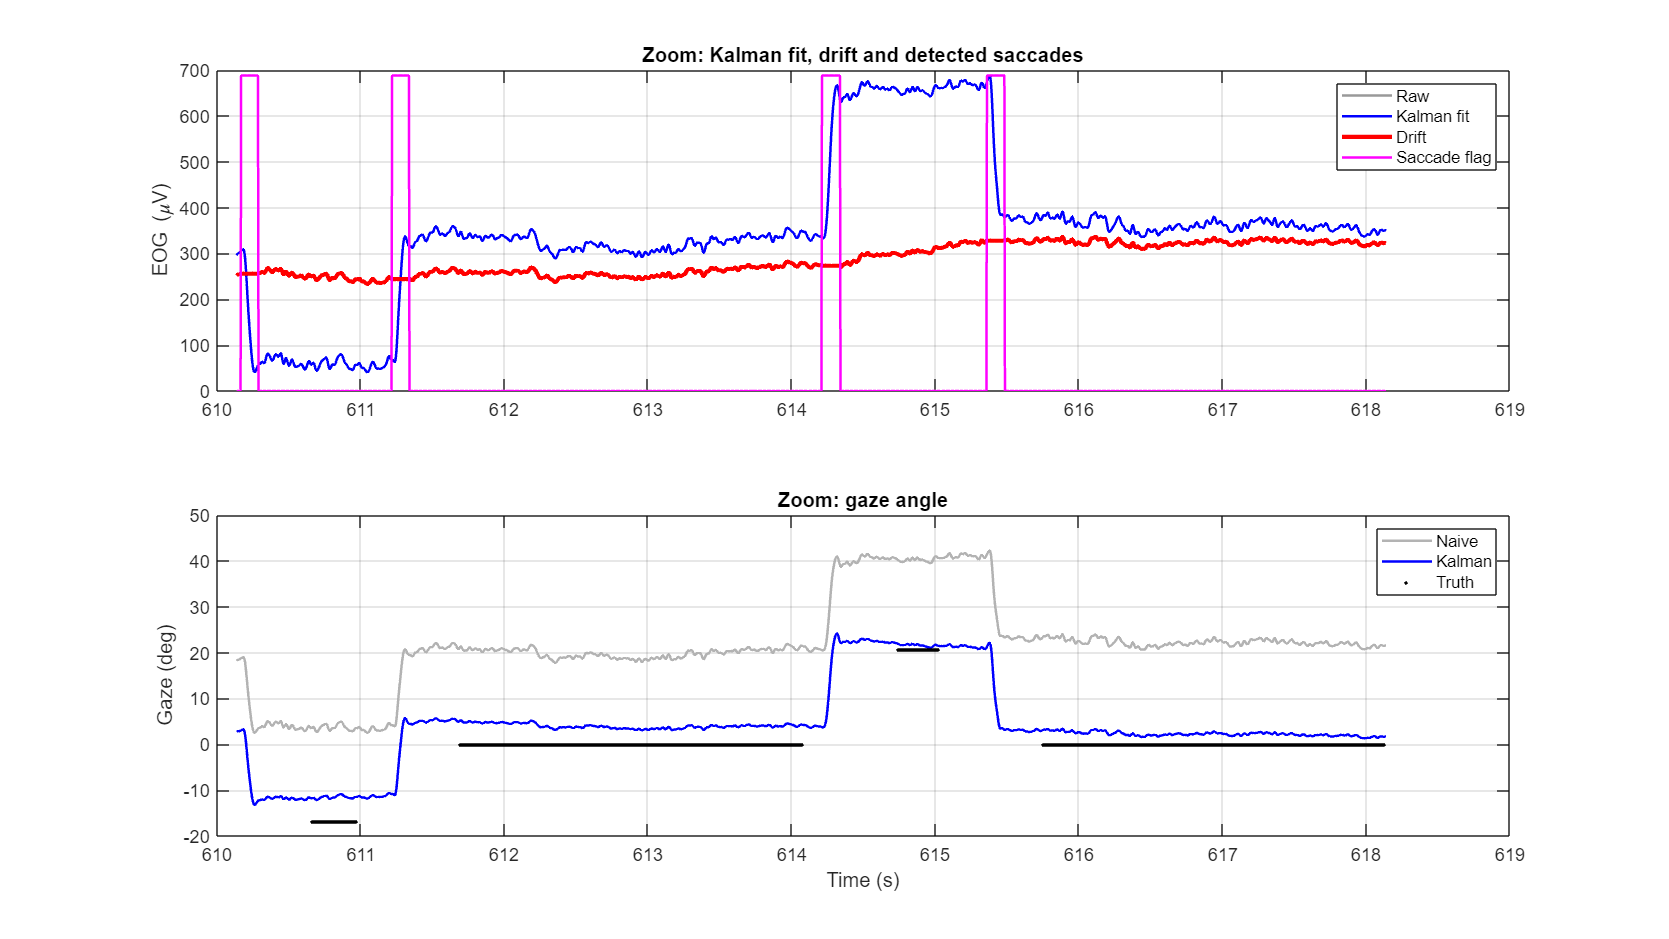

mid = round(N/2);  z = mid:min(N, mid+8*fs);
fig3 = figure('Position',[50 50 1920 1080],'Color','w');
subplot(2,1,1); plot(t(z),y(z),'Color',[.6 .6 .6]); hold on; plot(t(z),g*theta(z)+drift(z),'b');
plot(t(z),drift(z),'r','LineWidth',2.5); plot(t(z),isSacc(z)*max(y(z)),'m'); grid on; ylabel('EOG (\muV)');
title('Zoom: Kalman fit, drift and detected saccades'); legend('Raw','Kalman fit','Drift','Saccade flag');
subplot(2,1,2); plot(t(z),thetaNaive(z),'Color',[.7 .7 .7]); hold on; plot(t(z),theta(z),'b');
plot(t(z),truth(z),'k.','MarkerSize',6); grid on; xlabel('Time (s)'); ylabel('Gaze (deg)');
legend('Naive','Kalman','Truth'); title('Zoom: gaze angle');